# **Numerical properties of a whole body metabolic model**

**Authors: Ronan M.T. Fleming, Ines Thiele, University of Galway**

**Reviewers: **

**Derived from: **[**https://opencobra.github.io/cobratoolbox/stable/tutorials/tutorialNumCharact.html**](https://opencobra.github.io/cobratoolbox/stable/tutorials/tutorialNumCharact.html) 

## Introduction

During this tutorial, you will learn how to determine and explore the numerical properties of a large model, primarliy its stoichiometric matrix, but also its lower bounds, upper bounds, linear objective and right hand side of the constraints. Evaluating numerical properties are key to understanding whether one can expect problems when solving numerical optimisation problems on a whole body metabolic model. This tutorial is particularly useful when you have a multi-scale model and are facing numerical issues when performing flux balance analysis or any other variants of FBA.

## EQUIPMENT SETUP

## **Initialize the COBRA Toolbox.**

Please ensure that The COBRA Toolbox has been properly installed, and initialized using the `initCobraToolbox` function.

if 0 %set to true if your toolbox has not been initialised
    initCobraToolbox(false) % false, as we don't want to update
end

## PROCEDURE 

TIMING: 5 seconds - several hours (depending on the model size)

**Define the name of the model**

Throughout this tutorial, by default we will use a female whole body model.

%modelToUse  = 'iCoreED';
%modelToUse = 'iDopaNeuroC';
%modelToUse = 'Recon3T';
modelToUse = 'Harvey';
modelToUse = 'Harvetta';

if ~exist('model','var') %avoid loading large model repeatedly
    % Load the selected model and make any adjustments necessary.
    switch modelToUse
        case 'iCore'
            % If this is a distributed model, get the folder for the model. Commonly if you use your own model, this is unnecessary
            % As the file would be in the current folder. But for this tutorial we need to make sure, that the right model is used,
            % and that no other model with the same name is above it in the path.
            modelFolder = getDistributedModelFolder('ecoli_core_model.mat');

            % define the filename of the model
            modelFile = [modelFolder filesep 'ecoli_core_model.mat'];

            % load the modelToUse structure from the modelFile
            model = readCbModel(modelFile, 'modelToUse','model');
        case 'iCoreED'
            if ~exist('iCoreED','var')
                load ~/drive/sbgCloud/projects/variationalKinetics/data/iCoreED/iCoreED_modelT.mat
            end
            model    = modelT;

            if ~isfield(model,'biomassRxnAbbr')
                model.biomassRxnAbbr='Biomass_Ecoli_core_w_GAM';
            end
        case 'iDopaNeuroC'
            load('~/drive/sbgCloud/projects/variationalKinetics/data/iDopaNeuro/iDopaNeuroC.mat')
            %load('~/drive/sbgCloud/data/models/published/iDopaNeuro/iDopaNeuroC.mat')
            model = iDopaNeuroC;
            model.description='iDopaNeuroC';
            model.version='1.0';
        case 'Recon3T'
            load('~/drive/sbgCloud/projects/variationalKinetics/data/Recon3T/Recon3DModel_301_xomics_input.mat');
        case 'Harvey'
            load('~/drive/sbgCloud/code/wbm_modelingcode/WBM_reconstructions/Harvey_1_04c.mat')
            %load('~/drive/sbgCloud/projects/variationalKinetics/data/WBM/Harvey_1_04c.mat')
            %load('~/drive/sbgCloud/data/models/published/Harvey_Harvetta/20191104_Harvey_1_01c.mat')
            model=male;
            model.osenseStr='max';
            model = changeObjective(model,model.rxns(contains(model.rxns,'Whole')));

        case 'Harvetta'
            load('~/drive/sbgCloud/code/wbm_modelingcode/WBM_reconstructions/Harvetta_1_04c.mat')
            %load('~/drive/sbgCloud/projects/variationalKinetics/data/WBM/Harvetta_1_04c.mat')
            %load('~/drive/sbgCloud/data/models/published/Harvey_Harvetta/20191104_Harvetta_1_01c.mat')
            model=female;
            model.osenseStr='max';
            model = changeObjective(model,model.rxns(contains(model.rxns,'Whole')));
    end
end

**Load the stoichiometric matrix**

In order to use the model, we need to read the `modelFile` that contains a COBRA model structure  modelToUse:Some models contain stoichiometric matrices with a different name (commonly coupled models). By default, the stoichiometric matrix is denoted `S`.

% select the matrices
if isfield(model, 'S')
    if isfield(model,'b')
        S = [model.S,model.b];
    else
        S = model.S
    end
end

if isfield(model,'C')
    if isfield(model,'d')
        C = [model.C,model.d];
    else
        C = model.C
    end
else
    C = [];
end

**Basic numerical characteristics**

The **number of elements** represents the total number of entries in the stoichiometric matrix (including zero elements). This number is equivalent to the product of the number of reactions and the number of metabolites.

The number of rows represents the **number of metabolites** in the metabolic network. The number of columns corresponds to the **number of biochemical reactions** in the network.

% determine the number of reactions and metabolites in S
[nMets, nRxns] = size(S)

nMets = 60537

nRxns = 85893

% determine the number of elements in S
nElem = numel(S)  % Nmets * Nrxns

nElem = 5.1997e+09

The total number of nonzero elements corresponds to the total number of nonzero entries in the stoichiometric matrix (excluding zero elements).

% determine the number of nonzero elements in S
nNz = nnz(S)

nNz = 296032

**Sparsity and Density**

The **sparsity ratio** corresponds to a ratio of the number of zero elements and the total number of elements. The sparser a stoichiometric matrix, the fewer metabolites participate in each reaction. The sparsity ratio is particularly useful to compare models by how many metabolites participate in each reaction.

% determine the sparsity ratio of S (in percent)
sparsityRatio = (1 - nNz / nElem) * 100.0  % [%]

sparsityRatio = 99.9943

Similarly, the **complementary sparsity ratio** is calculated as the difference of 100 and the sparsity ratio expressed in percent, and therefore, is a ratio of the number of nonzero elements and the total number of elements.

% determine the complementary sparsity ratio (in percent)
compSparsityRatio = 100.0 - sparsityRatio  % [%]

compSparsityRatio = 0.0057

The** average column density **corresponds to a ratio of the number of nonzero elements in each column (i.e. reaction) and the total number of metabolites. The average column density corresponds to the arithmetic average of all the column densities (sum of all the reaction densities divided by the number of reactions).

% add the number of non-zeros in each column (reaction)
colDensityAv = 0;
for j = 1:nRxns
    colDensityAv = colDensityAv + nnz(S(:, j));
end

% calculate the arithmetic average number of non-zeros in each column
colDensityAv = colDensityAv / nRxns   % [-]

colDensityAv = 3.4465

The average column density provides a measure of how many stoichiometric coefficients participate in each biochemical reaction on average.

The **relative column density** corresponds to the ratio of the number of nonzero elements in each column and the total number of metabolites. The relative column density corresponds to the average column density divided by the total number of metabolites (expressed in percent). The relative column density may also be expressed as parts-per-million [ppm] for large-scale or huge-scale models. 

% determine the density proportional to the length of the column
colDensityRel = colDensityAv / nMets * 100  % [%]

colDensityRel = 0.0057

The relative column density indicates how many metabolites are being used on average in each reaction relative to the total number of metabolites in the metabolic network.

**Histogram**

[i,j,values]=find(S);
histogram(values(values~=1 & values ~=-1))
xlabel('nonzero coefficients (excluding -1,1)')
ylabel('# coefficient')

**Sparsity Pattern (spy plot)**

The visualisation of the sparsity pattern is useful to explore the matrix, spot inconsistencies, or identify patterns visually. In addition to the standard sparsity pattern, the magnitude of the elements of the stoichiometric matrix (stoichiometric coefficients) is shown as proportional to the size of the dot.

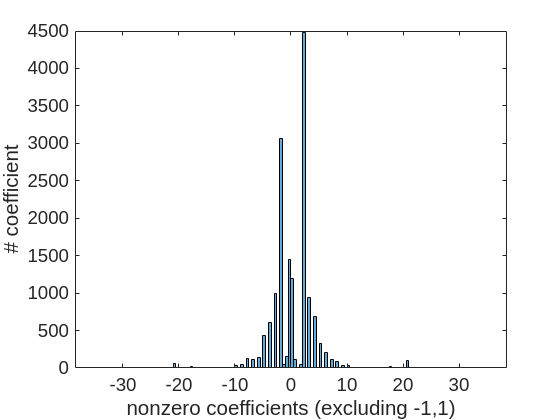

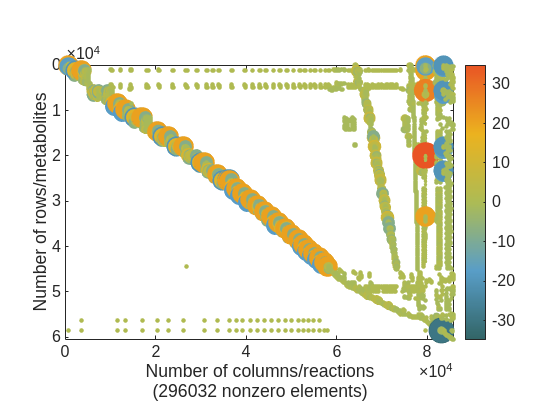

% print a colorful spy map of the S matrix
spyc(S, colormap(advancedColormap('cobratoolbox')),1,0);

Metabolites with large coefficients can be easily determined based on their dot size.

**Rank**

The **rank** of a stoichiometric matrix is the maximum number of linearly independent rows, and is equivalent to the number of linearly independent columns. The rank is a measurement of how many reactions and metabolites are linearly independent. 

% determine the rank of the stoichiometric matrix
if ispc
    rankS = rank(full(S))
else
    rankS = getRankLUSOL(S) % calculated using either the LUSOL solver [3]
end

rankS = 59318

The **rank deficiency** of the stoichiometric matrix is a measure of how many reactions and metabolites are not linearly dependent, and expressed as a ratio of the rank of the stoichiometric matrix to the theoretical full rank.

% calculate the rank deficiency (in percent)
rankDeficiencyS = (1 - rankS / min(nMets, nRxns)) * 100  % [%]

rankDeficiencyS = 2.0136

**Singular Values and Condition Number**

A singular value decomposition of the stoichiometric matrix is the decomposition into orthonormal matrices $U$ (of dimension `nMets` by `nMets`) and $V$ (of dimension `nRxns` by `nRxns`), and a matrix with nonnegative diagonal elements $D$ such that $\textrm{S}\;\textrm{=}\;\textrm{UD}V^T$.

Note that the calculation of singular values is numerically expensive, especially for large stoichiometric matrices.

if 0
% calculate the singular values
svVect = svds(S, rankS);

The `svds() `function returns the number of singular values specified in the second argument of the function. As most stoichiometric matrices are rank deficient, some singular values are zero (or within numerical tolerances). The cut-off is located at the rank of the stoichiometric matrix. 

% determine the vector with all singular values (including zeros)
svVectAll = svds(S, min(nMets, nRxns));

 --- SUMMARY ---
Model file/Model name/Matrix name    Harvetta/S
Size is [nMets, nRxns]               [60537, 85893]
Number of elements:                  5199704541 
Number of nonzero elements:          296032 
Sparsity ratio [%]:                  99.99 
Complementary sparsity ratio [%]     0.01 
Average column density [ppm]:        3.45 
Relative column density [ppm]:       0.01 
Rank:                                59318 
Rank deficiency [%]:                 2.01 
Maximum singular value:              NaN 
Minimum singular value:              NaN 
Condition number:                    NaN 


The singular values and their cut-off can be illustrated as follows:

% plot the singular values
figure;

nMets = 109757

nRxns = 85893


% plot the singular values up to rankS

nElem = 9.4274e+09

semilogy(linspace(1, length(svVect), length(svVect)), svVect, '*');

% plot all singular values

nNz = 221915

hold on;
semilogy(linspace(1, length(svVectAll), length(svVectAll)), svVectAll, 'ro');

% set the font size of the current figure axes, show a legend and minor grid axes
set(gca, 'fontsize', 14);

sparsityRatio = 99.9976

legend('svds (up to rankS)', 'svds (all)')
grid minor;


compSparsityRatio = 0.0024

% set the label
xlabel('Number of the singular value');
ylabel('Magnitude of the singular value');

hold off;

The** maximum singular** value is the largest element on the diagonal matrix obtained from singular value decomposition. Similarly, the **minimum singular value** is the smallest element on the diagonal matrix obtained from singular value decomposition. Only singular values greater than zero (numbered from `1` to `rank(S)`) are of interest.

% determine the maximum and minimum singular values
maxSingVal = svVect(1) % first value of the vector with singular values

colDensityAv = 2.5836

minSingVal = svVect(rankS) % smallest non-zero singular value

Alternatively, if the rank of the stoichiometric matrix `S` is not known, the built-in functions can also be used: 

maxSingValBuiltIn = svds(S, 1)

colDensityRel = 0.0024

minSingValBuiltIn = svds(S, 1, 'smallestnz')

The **condition number** of the stoichiometric matrix is a ratio of the maximum and minimum singular values. The higher this ratio, the more ill-conditioned the stoichiometric matrix is (numerical issues) and, generally, the longer the simulation time is.

% determine the condition number
condNumber = maxSingVal / minSingVal
else
    maxSingVal = NaN;
    minSingVal = NaN;
    condNumber = NaN;
end

**Summary of S or [S, b] characteristics**

The following numerical properties have been calculated:

- **Number of elements**: represents the total number of entries in the stoichiometric matrix (including zero elements). This number is equivalent to the product of the number of reactions and the number of metabolites.

- **Number of nonzero elements**: represents the total number of nonzero entries in the stoichiometric matrix (excluding zero elements).

- **Sparsity ratio**: ratio of the number of zero elements and the total number of elements. The sparser a stoichiometric matrix, the fewer metabolites participate in each reaction. The sparsity ratio is particularly useful to compare models by how many metabolites participate in each reaction.

- **Complementary sparsity ratio**: calculated as the difference of one and the sparsity ratio, and is the ratio of the number of nonzero elements and the total number of elements.

- **Average column density**: corresponds to the ratio of the number of nonzero elements in each column and the total number of metabolites. The average column density corresponds to the arithmetic average of all the column densities (sum of all the column densities divided by the number of reactions).

- **Relative column density**: corresponds to the ratio of the number of nonzero elements in each column and the total number of metabolites. The relative column density corresponds to the average column density divided by the total number of metabolites (expressed in parts-per-million (ppm)).

- **Rank**: the rank of a stoichiometric matrix is the maximum number of linearly independent rows and is equivalent to the number of linearly independent columns. The rank is a measurement of how many reactions and metabolites are linearly independent.

- **Rank deficiency**: the rank deficiency of the stoichiometric matrix is a measure of how many reactions and metabolites are linearly dependent, and expressed as the ratio of the rank of the stoichiometric matrix to the theoretical full rank.

- **Maximum singular value**: the largest element on the diagonal matrix obtained from singular value decomposition.

- **Minimum singular value**: the smallest element on the diagonal matrix obtained from singular value decomposition.

- **Condition number**: the condition number of the stoichiometric matrix is the ratio of the maximum and minimum singular values. The higher this ratio, the more ill-conditioned the stoichiometric matrix is (numerical issues).

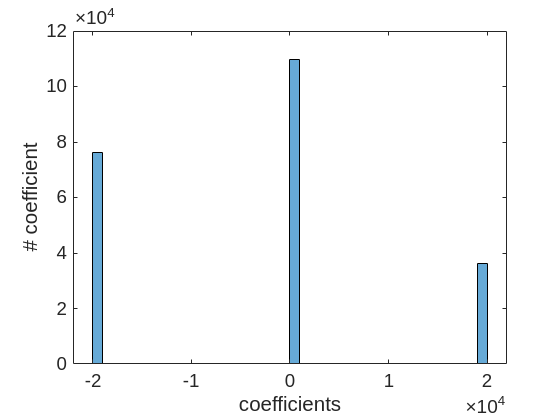

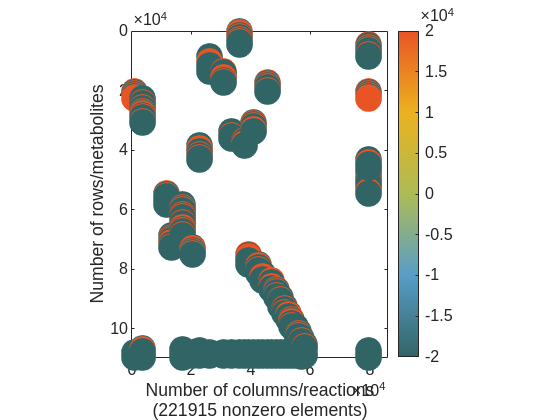

fprintf([' --- SUMMARY ---\n',...

    'Model file/Model name/Matrix name    %s/%s\n',...
    'Size is [nMets, nRxns]               [%d, %d]\n',...
    'Number of elements:                  %d \n',...
    'Number of nonzero elements:          %d \n',...
    'Sparsity ratio [%%]:                  %1.2f \n',...
    'Complementary sparsity ratio [%%]     %1.2f \n', ...
    'Average column density [ppm]:        %1.2f \n',...
    'Relative column density [ppm]:       %1.2f \n',...
    'Rank:                                %d \n',...
    'Rank deficiency [%%]:                 %1.2f \n',...

rankS = 74367

    'Maximum singular value:              %1.2f \n',...
    'Minimum singular value:              %1.2f \n',...
    'Condition number:                    %1.2f \n',...

rankDeficiencyS = 13.4190

    ],...
    modelToUse, 'S', nMets, nRxns, nElem, nNz, sparsityRatio, ...
    compSparsityRatio, colDensityAv, colDensityRel, rankS, rankDeficiencyS, ...
    maxSingVal, minSingVal, condNumber);

**Basic numerical characteristics of C or [C,d]**

The **number of elements** represents the total number of entries in the stoichiometric matrix (including zero elements). This number is equivalent to the product of the number of reactions and the number of metabolites.

The number of rows represents the **number of metabolites** in the metabolic network. The number of columns corresponds to the **number of biochemical reactions** in the network.

% determine the number of reactions and metabolites in C
[nMets, nRxns] = size(C)
% determine the number of elements in C
nElem = numel(C)  % Nmets * Nrxns

The total number of nonzero elements corresponds to the total number of nonzero entries in the stoichiometric matrix (excluding zero elements).

% determine the number of nonzero elements in C
nNz = nnz(C)

**Sparsity and Density**

The **sparsity ratio** corresponds to a ratio of the number of zero elements and the total number of elements. The sparser a stoichiometric matrix, the fewer metabolites participate in each reaction. The sparsity ratio is particularly useful to compare models by how many metabolites participate in each reaction.

% determine the sparsity ratio of C (in percent)
sparsityRatio = (1 - nNz / nElem) * 100.0  % [%]

Similarly, the **complementary sparsity ratio** is calculated as the difference of 100 and the sparsity ratio expressed in percent, and therefore, is a ratio of the number of nonzero elements and the total number of elements.

% determine the complementary sparsity ratio (in percent)
compSparsityRatio = 100.0 - sparsityRatio  % [%]

The** average column density **corresponds to a ratio of the number of nonzero elements in each column (i.e. reaction) and the total number of metabolites. The average column density corresponds to the arithmetic average of all the column densities (sum of all the reaction densities divided by the number of reactions).

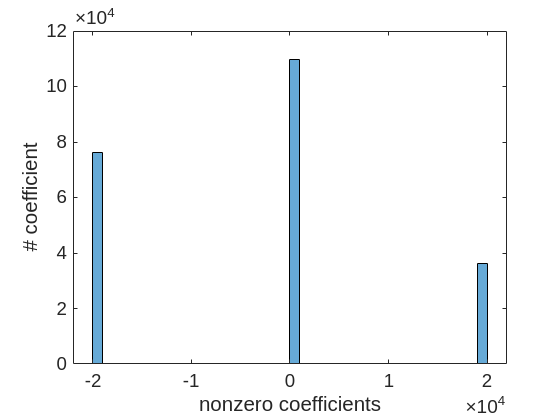

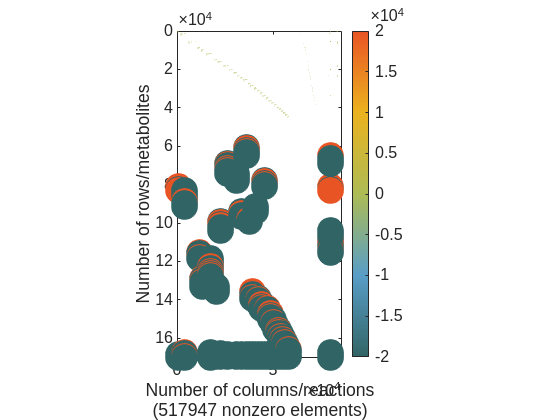

% add the number of non-zeros in each column (reaction)
colDensityAv = 0;

for j = 1:nRxns
    colDensityAv = colDensityAv + nnz(C(:, j));
end

% calculate the arithmetic average number of non-zeros in each column
colDensityAv = colDensityAv / nRxns   % [-]


 ------------------------ Scaling summary report ------------------------

 Estimation level:                             fine (scltol = 1.00)
 Name of matrix:                               SbCd
 Size of matrix:
        * rows:                           170294
        * cols:                           85893
 Coefficients:
        * Minimum (absolute non-zero value):   1.00e-06
        * Maximum (absolute non-zero value):   2.00e+04
 Lower bound coefficients:
        * Minimum (absolute non-zero value):   4.45e-07
        * Maximum (absolute non-zero value):   1.00e+06
 Upper bound coefficients:
        * Minimum (absolute non-zero value):   5.54e-09
        * Maximum (absolute non-zero value):   1.00e+06
 Row scaling coefficients:
        * Minimum:                             1.00e-02 (row #: 5895)
        * Maximum:                             2.00e+04 (row #: 68508)
 Column scaling coefficients:
        * Minimum:                             3.54e-02 (column #: 11955)
        * Max

The average column density provides a measure of how many stoichiometric coefficients participate in each biochemical reaction on average.

The **relative column density** corresponds to the ratio of the number of nonzero elements in each column and the total number of metabolites. The relative column density corresponds to the average column density divided by the total number of metabolites (expressed in percent). The relative column density may also be expressed as parts-per-million [ppm] for large-scale or huge-scale models. 

% determine the density proportional to the length of the column
colDensityRel = colDensityAv / nMets * 100  % [%]

solverRecommendation = 1×2 cell array
    {'dqqMinos'}    {'quadMinos'}


The relative column density indicates how many metabolites are being used on average in each reaction relative to the total number of metabolites in the metabolic network.

**Histogram**

[i,j,values]=find(C);

29  = # rows C(i,:)  with one entry
2430  = # rows C(i,:)  with three entries
Removing any coupling constraints with single
Replacing any triple-entry coupling constraints with two double entries

85892  = # cols model.C
109726  = # rows model.C
74336  = # rows C(i,:)*v < d(i)
35390  = # rows C(i,:)*v > d(i)
0  = # rows C(i,:)*v = d(i)
0  = # rows minus # rows C(i,:) < d(i) minus # rows C(i,:) > d(i)
109726  = # rows C(i,:)  with two entries
0  = # rows C(i,:)  with one entry
0  = # rows C(i,:)  with three entries
0  = # rows C(i,:)  with more than three entries
0  = # rows C(i,:)  without two entries
0  = # rows C(i,:)  without 1,2, or 3 entries
74336  = # rows C(i,:)  with both entries having opposite signs
35390  = # rows C(i,:)  with both entries having positive signs
0  = # rows C(i,:)  without two entries of any signs

Replacing 109726 badly-scaled coupling constraints with sequences of
well-scaled coupling constraints. This may take a few minutes.


histogram(values)
xlabel('coefficients')
ylabel('# coefficient')

**Sparsity Pattern (spy plot)**

The visualisation of the sparsity pattern is useful to explore the matrix, spot inconsistencies, or identify patterns visually. In addition to the standard sparsity pattern, the magnitude of the elements of the stoichiometric matrix (stoichiometric coefficients) is shown as proportional to the size of the dot.

% print a colorful spy map of the C matrix
spyc(C, colormap(advancedColormap('cobratoolbox')),1,0);

Metabolites with large coefficients can be easily determined based on their dot size.

**Rank**

The **rank** of a stoichiometric matrix is the maximum number of linearly independent rows, and is equivalent to the number of linearly independent columns. The rank is a measurement of how many reactions and metabolites are linearly independent. 

% determine the rank of the stoichiometric matrix
if ispc
    rankS = rank(full(C))
else
    rankS = getRankLUSOL(C) % calculated using either the LUSOL solver [3]
end

The **rank deficiency** of the stoichiometric matrix is a measure of how many reactions and metabolites are not linearly dependent, and expressed as a ratio of the rank of the stoichiometric matrix to the theoretical full rank.

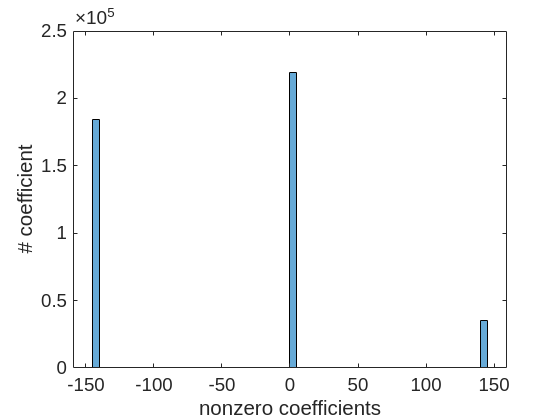

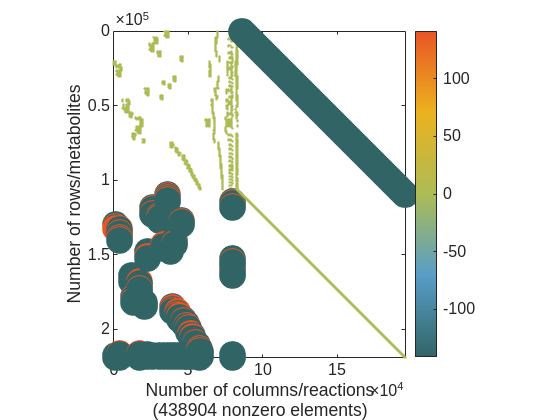

% calculate the rank deficiency (in percent)

rankDeficiencyS = (1 - rankS / min(nMets, nRxns)) * 100  % [%]

**Singular Values and Condition Number**

A singular value decomposition of the stoichiometric matrix is the decomposition into orthonormal matrices $U$ (of dimension `nMets` by `nMets`) and $V$ (of dimension `nRxns` by `nRxns`), and a matrix with nonnegative diagonal elements $D$ such that $\textrm{S}\;\textrm{=}\;\textrm{UD}V^T$.

Note that the calculation of singular values is numerically expensive, especially for large stoichiometric matrices.

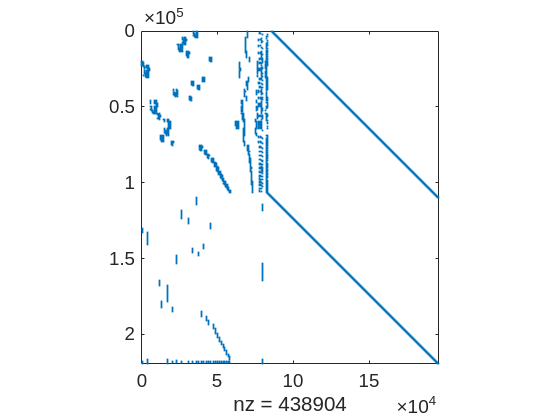

if 0

% calculate the singular values
svVect = svds(C, rankS);


 ------------------------ Scaling summary report ------------------------

 Estimation level:                             fine (scltol = 1.00)
 Name of matrix:                               SbCd
 Size of matrix:
        * rows:                           279989
        * cols:                           85893
 Coefficients:
        * Minimum (absolute non-zero value):   1.00e-06
        * Maximum (absolute non-zero value):   1.41e+02
 Lower bound coefficients:
        * Minimum (absolute non-zero value):   4.45e-07
        * Maximum (absolute non-zero value):   1.00e+06
 Upper bound coefficients:
        * Minimum (absolute non-zero value):   5.54e-09
        * Maximum (absolute non-zero value):   1.00e+06
 Row scaling coefficients:
        * Minimum:                             2.14e-03 (row #: 20273)
        * Maximum:                             1.09e+04 (row #: 213517)
 Column scaling coefficients:
        * Minimum:                             5.88e-03 (column #: 79696)
        * M

The `svds() `function returns the number of singular values specified in the second argument of the function. As most stoichiometric matrices are rank deficient, some singular values are zero (or within numerical tolerances). The cut-off is located at the rank of the stoichiometric matrix. 

% determine the vector with all singular values (including zeros)
svVectAll = svds(C, min(nMets, nRxns));

The singular values and their cut-off can be illustrated as follows:

% plot the singular values
figure;

% plot the singular values up to rankS
semilogy(linspace(1, length(svVect), length(svVect)), svVect, '*');

% plot all singular values
hold on;
semilogy(linspace(1, length(svVectAll), length(svVectAll)), svVectAll, 'ro');

% set the font size of the current figure axes, show a legend and minor grid axes
set(gca, 'fontsize', 14);
legend('svds (up to rankS)', 'svds (all)')
grid minor;

% set the label
xlabel('Number of the singular value');
ylabel('Magnitude of the singular value');

hold off;

The** maximum singular** value is the largest element on the diagonal matrix obtained from singular value decomposition. Similarly, the **minimum singular value** is the smallest element on the diagonal matrix obtained from singular value decomposition. Only singular values greater than zero (numbered from `1` to `rank(C)`) are of interest.

% determine the maximum and minimum singular values
maxSingVal = svVect(1) % first value of the vector with singular values
minSingVal = svVect(rankS) % smallest non-zero singular value

Alternatively, if the rank of the stoichiometric matrix C is not known, the built-in functions can also be used: 

maxSingValBuiltIn = svds(C, 1)
minSingValBuiltIn = svds(C, 1, 'smallestnz')

The **condition number** of the stoichiometric matrix is a ratio of the maximum and minimum singular values. The higher this ratio, the more ill-conditioned the stoichiometric matrix is (numerical issues) and, generally, the longer the simulation time is.

% determine the condition number
condNumber = maxSingVal / minSingVal
else
    maxSingVal = NaN;
    minSingVal = NaN;
    condNumber = NaN;
end

## Coupling constraints

**2.1.3 Coupling constraints**

"Coupling constraints were implemented in the WBM reconstructions as described previously (Thiele *et al*, [2010](https://www.embopress.org/doi/full/10.15252/msb.20198982#core-msb198982-cit-0090); Heinken *et al*, [2013](https://www.embopress.org/doi/full/10.15252/msb.20198982#core-msb198982-cit-0037)). Briefly, coupling constraints enforce that the flux through a set of coupled reactions is proportional to a specified reaction (e.g., biomass reaction). The metabolic and transport reactions in every organ were coupled to the respective organ's biomass objective function (BOF). The coupling constraints prevent biologically implausible solutions where the reactions in an organs carry flux even though the flux through the organ's BOF is zero. They were realized by implementing a coupling factor of 20,000 for each reaction. This allowed each forward and reverse reaction to carry a flux of up to 20,000 and −20,000 times the flux through the BOF, respectively." - Source [https://www.embopress.org/doi/full/10.15252/msb.20198982](https://www.embopress.org/doi/full/10.15252/msb.20198982) 

**Histogram**

[i,j,values]=find(C);
histogram(values)
xlabel('nonzero coefficients')
ylabel('# coefficient')

**Sparsity Pattern (spy plot) of S and C**

The visualisation of the sparsity pattern is useful to explore the matrix, spot inconsistencies, or identify patterns visually. In addition to the standard sparsity pattern, the magnitude of the elements of the stoichiometric matrix (stoichiometric coefficients) is shown as proportional to the size of the dot.

% print a colorful spy map of the C matrix
spyc([S;C], colormap(advancedColormap('cobratoolbox')),1,0);

**Scaling**

The scaling estimate is based on the order of magnitude of the ratio of the maximum and minimum scaling coefficients, which are determined such that the scaled stoichiometric matrix has entries close to unity. In order to investigate the scaling of the stoichiometric matrix and provide an estimate of the most appropriate precision of the solver to be used, the following quantities should be calculated:

- **Estimation level: **The estimation level, defined by the parameter scltol provides a measure of how accurate the estimation is. The estimation level can be *crude*, *medium*, or *fine*.

- **Size of the matrix: **The size of the matrix indicates the size of the metabolic network, and is broken down into number of metabolites and number of reactions.

- **Stoichiometric coefficients:** The maximum and minimum values of the stoichiometric matrix provide a range of the stoichiometric coefficients and are determined based on all elements of the stoichiometric matrix. Their ratio (and its order of magnitude) provides valuable information on the numerical difficulty to solve a linear program.

- **Lower bound coefficients: **The maximum and minimum values of the lower bound vector provide a range of the coefficients of the lower bound vector. Their ratio (and its order of magnitude) provides valuable information on the numerical difficulty to solve a linear program.

- **Upper bound coefficients: **The maximum and minimum values of the upper bound vector provide a range of the coefficients of the upper bound vector. Their ratio (and its order of magnitude) provides valuable information on the numerical difficulty to solve a linear program.

- **Row scaling coefficients: **The row scaling coefficients are the scaling coefficients required to scale each row closer to unity. The maximum and minimum row scaling coefficients provide a range of row scaling coefficients required to scale the stoichiometric matrix row-wise. Their ratio (and its order of magnitude) provides valuable information on the numerical difficulty to solve a linear program. 

- **Column scaling coefficients: **The column scaling coefficients are the scaling coefficients required to scale each column closer to unity. The maximum and minimum column scaling coefficients provide a range of column scaling coefficients required to scale the stoichiometric matrix column-wise. Their ratio (and its order of magnitude) provides valuable information on the numerical difficulty to solve a linear program.

The scaling properties of the stoichiometric matrix can be determined using:

[precisionEstimate, solverRecommendation] = checkScaling(model,'fine',1);

In this case, the `solverRecommendation` is:

solverRecommendation

## Lifting the coupling constraints of a whole body metabolic model

**Coupling constraints **With coupling constraints two fluxes could be related by

v1 ≤ 10000*v2.

(6)

One can decompose these constraints into sequences of constraints involving auxiliary variables with reasonable coefficients. If the second inequality in (6) were presented to our implementation as *v*1 ≤ 10000**v*2, we would transform it to two constraints involving an auxiliary variable *s*1:

v1 ≤ 100*s1,    s1 ≤ 100* v2.

(7)

**Hierarchical lifting** [6] uses a parameter *τ = *BIG, set to 1000 by default. Constraints containing entries larger than *τ* are reformulated. Very large entries might require more than one auxiliary variable and constraint. In these cases, we choose the reformulated constraint coefficients to be equally spaced in logarithmic scale. For example, the poorly scaled reaction

A+10^9*B→C+D

(with |109| > *τ*) would be reformulated as

A+1000*B1→C+D,

1000*B2→B1,

1000*B→B2

(with |1000|≤*τ*). 

Implement lifting of coupling constraints in a whole body model:

INPUTS:

   model: 

                        * S  - `m x n` Stoichiometric matrix

                        * c  - `n x 1` Linear objective coefficients

                        * lb - `n x 1` Lower bounds on net flux

                        * ub - `n x 1` Upper bounds on net flux

                        * b - `m x 1` change in concentration with time

                        * csense - `m x 1` character array with entries in {L,E,G}

                        * mets `m x 1` metabolite abbreviations

                        * C - `k x n` Left hand side of C*v <= d

                        * d - `k x 1` Right hand side of C*v <= d

                        * ctrs `k x 1` Cell Array of Strings giving IDs of the coupling constraints

                        * dsense - `k x 1` character array with entries in {L,E,G}

OPTIONAL INPUTS

   'BIG'                Value consided a large coefficient. BIG should be set between 1000 and 10000 on double precision machines.

   `printLevel`         1 or 0 enables/diables printing respectively.

model_lifted = liftCouplingConstraints(model);

OUTPUTS:

   model: 

                        * E	               m x evars	   Sparse or Full Matrix of Double	Matrix of additional, non metabolic variables (e.g. Enzyme capacity variables)

                        * C	                ctrs x n	    Sparse or Full Matrix of Double	Matrix of additional Constraints (e.g. Coupling Constraints)

                        * D	              ctrs x evars	Sparse or Full Matrix of Double	Matrix to store elements that contain interactions between additional Constraints and additional Variables.

                        * evarlb	        evars x 1	    Column Vector of Doubles	Lower bounds of the additional variables

                        * evarub	        evars x 1	    Column Vector of Doubles	Upper bounds of the additional variables

                        * evarc	        evars x 1	    Column Vector of Doubles	Objective coefficient of the additional variables

                        * evars	        evars x 1	    Column Cell Array of Strings	IDs of the additional variables

                        * evarNames	evars x 1	    Column Cell Array of Strings	Names of the additional variables

                        * ctrs	         ctrs x 1	    Column Cell Array of Strings	IDs of the additional Constraints

                        * ctrNames	 ctrs x 1	    Column Cell Array of Strings	Names of the of the additional Constraints

                        * d	                 ctrs x 1	    Column Vector of Doubles	Right hand side values of the additional Constraints

                        * dsense	         ctrs x 1	    Column Vector of Chars	Senses of the additional Constraints

   The linear optimisation problem derived from this model is then of the form

                         [S, E; C, D]*x  <=>  [b;d]    

**Histogram**

[i,j,values]=find([model_lifted.C,model_lifted.D]);
histogram(values)
xlabel('nonzero coefficients')
ylabel('# coefficient')

**Sparsity Pattern (spy plot) of S and C**

The visualisation of the sparsity pattern is useful to explore the matrix, spot inconsistencies, or identify patterns visually. In addition to the standard sparsity pattern, the magnitude of the elements of the stoichiometric matrix (stoichiometric coefficients) is shown as proportional to the size of the dot.

% print a colorful spy map of the C matrix
spyc([model_lifted.C,model_lifted.D], colormap(advancedColormap('cobratoolbox')),1,0);

spy([model_lifted.C,model_lifted.D])

Check scaling of lifted model

[precisionEstimate, solverRecommendation] = checkScaling(model_lifted,'fine',1);

## EXPECTED RESULTS

The expected result is a summary table with relevant numerical characteristics and a recommendation of the precision of the solver.

## TROUBLESHOOTING

If any numerical issues arise (e.g., infeasible solution status after performing flux balance analysis, or too long simulation times) when using a double precision solver, then a higher precision solver should be tested. For instance, a double precision solver may incorrectly report that an ill-scaled optimisation problem is infeasible although it actually might be feasible for a higher precision solver. 

In some cases,  the precision recommendation might not be accurate enough and a double precision solver might lead to inaccurate results. Try a quad precision solver in order to confirm the results when in doubt.

The `checkScaling()` function may be used on all operating systems, but the `'dqqMinos'` interface is only available on UNIX operating systems. If the `'dqqMinos'` interface is not working as intended, the binaries might not be compatible (raise an issue if they are not by providing the output of `generateSystemConfigReport`). Make sure that all relevant system requirements are satisfied before trying to use the `'dqqMinos'` solver interface.

In case the `'dqqMinos' `interface reports an error when trying to solve the linear program, there might be an issue with the model itself.

## References

[1] [Thiele et al., A community-driven global reconstruction of human metabolism, Nat Biotech, 2013.](http://www.nature.com/nbt/journal/v31/n5/full/nbt.2488.html)

[2] Reconstruction and Use of Microbial Metabolic Networks: the Core Escherichia coli Metabolic Model as an Educational Guide by Orth, Fleming, and Palsson (2010)

[3] P. E. Gill, W. Murray, M. A. Saunders and M. H. Wright (1987). Maintaining LU factors of a general sparse matrix, Linear Algebra and its Applications 88/89, 239-270.

[4] Multiscale modeling of metabolism and macromolecular synthesis in E. coli and its application to the evolution of codon usage, Thiele et al., PLoS One, 7(9):e45635 (2012).

[5] D. Ma, L. Yang, R. M. T. Fleming, I. Thiele, B. O. Palsson and M. A. Saunders, Reliable and efficient solution of genome-scale models of Metabolism and macromolecular Expression, Scientific Reports 7, 40863; doi: \url{10.1038/srep40863} (2017). [http://rdcu.be/oCpn.](http://rdcu.be/oCpn.)

[6] Sun, Y., Fleming, R.M., Thiele, I., Saunders, M. Robust flux balance analysis of multiscale biochemical reaction networks. BMC Bioinformatics 14, 240 (2013). [https://doi.org/10.1186/1471-2105-14-240](https://doi.org/10.1186/1471-2105-14-240) [https://bmcbioinformatics.biomedcentral.com/articles/10.1186/1471-2105-14-240](https://bmcbioinformatics.biomedcentral.com/articles/10.1186/1471-2105-14-240)  